A =          0    1.0000   -1.0000    1.0000
         0    1.0000         0         0
         0         0         0         0
   -0.2000   -0.1000    1.0000    1.0000


B =      0     0
     1     1
     4     0
     0     0



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


zopt =     8.2485
  123.2581
   -0.1893
   19.2077
    7.3104
  -14.1176
   84.6557
   64.2360
    0.3727
   -4.3636


Jopt = 3.5079

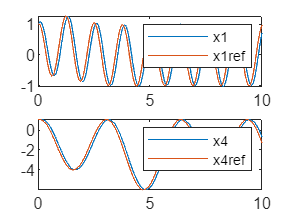

clc;clear all;close all;

%step(GCL,40);hold on
nx=4;
nu=2;
n_f_b=4;

syms x [4 1]
syms u [2 1]
syms t
A=jacobian(pend(t,x,u),x);
B=jacobian(pend(t,x,u),u);
xd=[0;0;0;-2];ud=[zeros(2,1)];
A=double(subs(A,[x;u],[xd;ud]))
B=double(subs(B,[x;u],[xd;ud]))
K0=lqr(A,B,diag([100 1 1 100]),diag([0.1 0.1]));
z0=[K0(:);zeros(nu+nu*n_f_b,1)];
options=optimoptions("fmincon","MaxFunctionEvaluations",12000);

i = 1;
x0=[1;1;1;1];
[zopt,Jopt]=fmincon(@(z)costo(z,i,x0),z0,[],[],[],[],[],[],@(z)restr(z,A,B),options)
[T,X]=ode45(@(t,x)pend(t,x,control(t,x,zopt)),[0 10],x0);
figure()
subplot(211)
plot(T,X(:,1));hold on;
plot(T,exp(-T).*sin(T)+cos(5*T));
legend('x1','x1ref')
subplot(212)
plot(T,X(:,4)); hold on;
plot(T,-2+sin(T)+3*cos(2*T));
legend('x4','x4ref')



function J=costo(z,i,x0)
    fun=@(t,x)pend(t,x,control(t,x,z));
    Ts=0.1;
    T=(0:Ts:6)';xk=x0;
    U=[];Ye=[];
    for k=1:length(T)
        U=[U;control(k*Ts,xk,z)];
        k1=fun(k*Ts,xk);
        k2=fun(k*Ts+Ts/2,xk+k1*Ts/2);
        k3=fun(k*Ts+Ts/2,xk+k2*Ts/2);
        k4=fun(k*Ts+Ts,xk+k3*Ts);
        xk=xk+Ts*(k1+2*k2+2*k3+k4)/6;
        yk=[1 0 0 0;0 0 0 1]*xk; %----> seleccionas las salidas
        t=Ts*k;
        yrefk=[exp(-t)*sin(t)+cos(5*t);-2+sin(t)+3*cos(2*t)]; %---> pones las referencias
        Ye=[Ye;yk-yrefk];
    end
    if(i==1)
        J=sum(abs(Ye))+0.0001*sum((U.^2));
    elseif(i==2)
        J=sum(abs(Ye).*T)+0.01*sum((U.^2));
    elseif(i==3)
        J=sum((Ye).^2)+0.01*sum((U.^2));
    elseif(i==4)
        J=sum(sum((Ye).^2)'.*T)+0.0001*sum((U.^2));
    end
end

function [c,c_eq]=restr(z,A,B)
    nx=4;
    nu=2;
    n_f_b=4;
    K=z(1:(nu*nx));
    K=reshape(K,[nu nx]);%nu nx
    c=[max(real(eig(A-B*K)))+0.2];%%
    c_eq=[];
end
function u=control(t,x,z)
    nx=4;
    nu=2;
    n_f_b=4;
    K=z(1:(nu*nx));
    K1=z((nu*nx)+(1:nu));
    K2=z(nu*nx+nu+(1:(nu*n_f_b)));
    K=reshape(K,[nu nx]);%nu nx
    K2=reshape(K2,[nu n_f_b]);%nu n_f_b
    u=-K*x+K1+K2*[exp(-t)*sin(t)+cos(5*t);-2+sin(t)+3*cos(2*t);exp(-t)*(cos(t)-sin(t))-5*sin(5*t);cos(t)-6*sin(3*t)];
end
 
function dx=pend(t,x,u)
    dx=[x(2)+x(4)-x(3);
atan(x(2))+cos(5*(x(1))+x(2))+u(1)+u(2);
-0.1*x(1)^3+4*u(1);
-0.2*x(1)-0.1*x(2)+x(4)+x(3)];
end
